clc;
close all;
clear all;
format long;
warning('off');
cd("G:\My Drive\Ph.D. Files (UC Davis)\Courseworks\EEC201 – Digital Signal Processing\Project\Project 2021\Simulation Files\Data\Training_Data");

NFB = 40;      % Number of Mel Filter Banks
NFFT = 256;
w = linspace(0,2*pi,NFFT);

for j=1:1:8
    filename = 's' + string(j) + '.wav';
    [Audio,fs] = audioread(filename);
    Ts = 1/fs;
    t = (0:1:length(Audio)-1)*Ts;
    data{j}= {Audio,t',fs};
end
% sound()

N = 256;         % Frame Length
M = 100;         % Frame overlap

for i=1:1:length(data)
frame{i} = Frame_Blocking(data{i}{1},N,M);    % Frame Blocking
xn{i} = hamming_window(frame{i},N);           % Hamming Window     
Sxk{i} = fft(xn{i});
Sxk{i} = Sxk{i}(1:end/2,:);
Mag_Sxk{i} = abs(Sxk{i}).^2;                  % PSD 
end

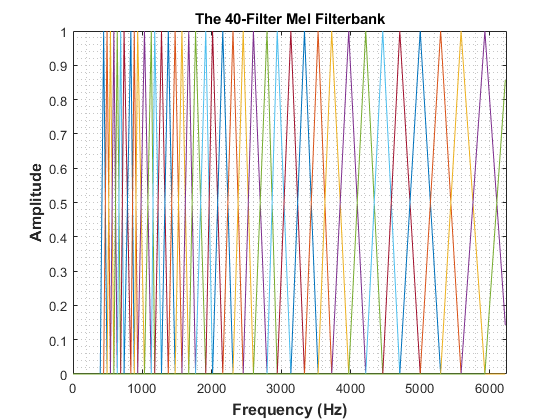

f = (w)/(2*pi*Ts);
H = MELFB(NFB,NFFT/2,Ts);       % Recalling mel-spaced filterbank
for m=1:1:length(H(:,1))
    plot(f(1:end/2),H(m,:));hold on;
end
xlabel('Frequency (Hz)','fontweight','bold','fontsize',12);
ylabel('Amplitude','fontweight','bold','fontsize',12);xlim([0 fs/2]);
title('The 40-Filter Mel Filterbank');grid minor

for i=1:1:length(data)
    Mel_Spectrum_out {i} = Mel_Spectrum( H, Mag_Sxk{i} );
end

Error: File: Mel_Spectrum.m Line: 1 Column: 52
Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.





% A = zeros(NFFT/2,1);
% for i=1:1:length(Mag_Sxk(1:end/2))
%     for j=1:1:length(Mag_Sxk{1})
%         for m=1:1:NFB
%             A = sum(Mag_Sxk{i}{j}.*H(m,:)');
%         end
%         Mel_Spectrum{i}{j} = A;
%     end
% end